# Sampling

Leggo il csv con le immagini del train pulito

file_csv = '../visual_proj/clean_train80/clean_train80_info.csv';

data = readtable(file_csv);

Grafico di distribuzione

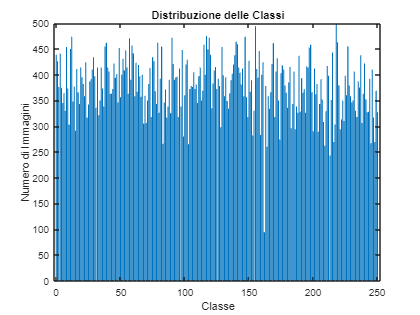

classColumn = data(:, 2);

classes = table2array(classColumn);

histogramData = hist(classes, 0:251);

figure;
bar(0:251, histogramData);
xlabel('Classe');
ylabel('Numero di Immagini');
title('Distribuzione delle Classi');

## Undersampling -randomico-


% Identificazione delle classi maggioritarie
classiUniche = unique(data{:, 2});
conteggioClassi = histc(data{:, 2}, classiUniche);
classiMaggioritarie = classiUniche(conteggioClassi > 300);
classiMinoritarie = classiUniche(conteggioClassi <= 300);

nomiColonne = {'ImageName', 'Class'};
nuoviDati = table('Size', [0, width(data)], 'VariableTypes', varfun(@class, data, 'OutputFormat', 'cell'), 'VariableNames', nomiColonne);


% Undersampling
for i = 1:numel(classiMaggioritarie)

    disp(['La classe considerata è la numero ', num2str(i), ' di ', num2str(numel(classiMaggioritarie))]);

    classeAttuale = classiMaggioritarie(i);
    indiciClasse = find(data{:, 2} == classeAttuale);
    
    if numel(indiciClasse) > 300
        indiciCampione = datasample(indiciClasse, 300, 'Replace', false);
        nuoviDati = [nuoviDati; data(indiciCampione, :)];
    else
        nuoviDati = [nuoviDati; data(indiciClasse, :)];
    end
end

La classe considerata è la numero 1 di 231
La classe considerata è la numero 2 di 231
La classe considerata è la numero 3 di 231
La classe considerata è la numero 4 di 231
La classe considerata è la numero 5 di 231
La classe considerata è la numero 6 di 231
La classe considerata è la numero 7 di 231
La classe considerata è la numero 8 di 231
La classe considerata è la numero 9 di 231
La classe considerata è la numero 10 di 231
La classe considerata è la numero 11 di 231
La classe considerata è la numero 12 di 231
La classe considerata è la numero 13 di 231
La classe considerata è la numero 14 di 231
La classe considerata è la numero 15 di 231
La classe considerata è la numero 16 di 231
La classe considerata è la numero 17 di 231
La classe considerata è la numero 18 di 231
La classe considerata è la numero 19 di 231
La classe considerata è la numero 20 di 231
La classe considerata è la numero 21 di 231
La classe considerata è la numero 22 di 231
La classe considerata è la numero 23 di 2


indiciClassiInteressate = ismember(data{:, 2}, classiMinoritarie);
nuoviDati = [nuoviDati; data(indiciClassiInteressate, :)];

cartellaVecchio = '../visual_proj/clean_train80/clean_train80/';
cartellaNuovo = '../visual_proj/clean_train80/clean_train80_sampling/';


Creo cartella e csv con immagini corrispondenti

for i = 1:height(nuoviDati)
    nomeImmagine = nuoviDati{i, 1}; % Assumendo che la prima colonna contenga i nomi delle immagini
    percorsoVecchio = fullfile(cartellaVecchio, nomeImmagine);
   
    if mod(i, 1000) == 0
        disp(['Immagine considerata ', num2str(i), ' di ', num2str(height(nuoviDati))]);
    end
    % Leggi l'immagine
    immagine = imread(percorsoVecchio{1});
    
    % Salva l'immagine nella cartella NUOVO
    percorsoNuovo = fullfile(cartellaNuovo, nomeImmagine);
    imwrite(immagine, percorsoNuovo{1});
end

Immagine considerata 1000 di 74666
Immagine considerata 2000 di 74666
Immagine considerata 3000 di 74666
Immagine considerata 4000 di 74666
Immagine considerata 5000 di 74666
Immagine considerata 6000 di 74666
Immagine considerata 7000 di 74666
Immagine considerata 8000 di 74666
Immagine considerata 9000 di 74666
Immagine considerata 10000 di 74666
Immagine considerata 11000 di 74666
Immagine considerata 12000 di 74666
Immagine considerata 13000 di 74666
Immagine considerata 14000 di 74666
Immagine considerata 15000 di 74666
Immagine considerata 16000 di 74666
Immagine considerata 17000 di 74666
Immagine considerata 18000 di 74666
Immagine considerata 19000 di 74666
Immagine considerata 20000 di 74666
Immagine considerata 21000 di 74666
Immagine considerata 22000 di 74666
Immagine considerata 23000 di 74666
Immagine considerata 24000 di 74666
Immagine considerata 25000 di 74666
Immagine considerata 26000 di 74666
Immagine considerata 27000 di 74666
Immagine considerata 28000 di 74666
I

writetable(nuoviDati, '../visual_proj/clean_train80/clean_train80_sampling.csv');

## Oversampling

data = nuoviDati;

classColumn = data(:, 2);

classes = table2array(classColumn);

targetNumImages = 300;

% Identificazione delle classi minoritarie
uniqueClasses = unique(classes);
minorityClasses = uniqueClasses(hist(classes, uniqueClasses) < targetNumImages);

imds = imageDatastore('../visual_proj/clean_train80/clean_train80_sampling');

colonna_dati = data.Class;

labels = categorical(colonna_dati);

imds= imageDatastore('../visual_proj/clean_train80/clean_train80_sampling', 'labels', labels);

datiAggiornati=data

datiAggiornati = 74666×2 table
         ImageName          Class
    ____________________    _____

    {'train_059622.jpg'}      0  
    {'train_059587.jpg'}      0  
    {'train_059880.jpg'}      0  
    {'train_059938.jpg'}      0  
    {'train_059811.jpg'}      0  
    {'train_059903.jpg'}      0  
    {'train_059906.jpg'}      0  
    {'train_059660.jpg'}      0  
    {'train_059731.jpg'}      0  
    {'train_059774.jpg'}      0  
    {'train_059522.jpg'}      0  
    {'train_059414.jpg'}      0  
    {'train_059892.jpg'}      0  
    {'train_059735.jpg'}      0  
    {'train_059869.jpg'}      0  
    {'train_059928.jpg'}      0  


pixelRange = [-5 5];
scaleUpRange = [1.1 1.2]; 
scaleDownRange = [0.9 0.8]; 

imageAugmenter = imageDataAugmenter(...
    'RandXReflection', true, ...
    'RandYReflection', true, ...
    'RandXTranslation', pixelRange, ...
    'RandYTranslation', pixelRange, ...
    'RandRotation', pixelRange, ...
    'RandScale', [1,1], ...
    'RandXShear', [-1,1], ...
    'RandYShear', [-1,1]);


augimdsVal=augmentedImageDatastore([224 224 3],imds,...
    'DataAugmentation',imageAugmenter);

for i = 1:numel(minorityClasses)
    currentClass = minorityClasses(i);
    idx = find(data.Class == currentClass);
    imagesNames = data.ImageName(idx);
    imagePaths = fullfile('../visual_proj/clean_train80/clean_train80_sampling', imagesNames);
    
    % Calcolo quanti duplicati sono necessari
    numDuplicates = targetNumImages - numel(idx);
    
    augmentedImages = cell(numDuplicates, 1);
    
    disp(['La classe considerata è la numero ', num2str(i), ' di ', num2str(numel(minorityClasses))]);
    
    for j = 1:numDuplicates
        
        if mod(j, 50) == 0
            disp(['Il duplicato è ', num2str(j), ' di ', num2str(numDuplicates)]);
        end

        imgIdx = randi(numel(imagePaths));
        img = imread(imagePaths{imgIdx});
        
        augmentedImg = augment(imageAugmenter, img);

        outputFolder = '../visual_proj/clean_train80/clean_train80_sampling'; % Sostituisci con il percorso della tua cartella
        outputFilename = sprintf('%s_augmented_%d.jpg', num2str(currentClass), j);

        imwrite(augmentedImg, fullfile(outputFolder, outputFilename));

        nuovaRigaCell = {outputFilename, num2str(currentClass)};
        nuovaRigaCell{2} = str2double(nuovaRigaCell{2});

        datiAggiornati = [datiAggiornati; nuovaRigaCell];

    end
end

La classe considerata è la numero 1 di 20


Unrecognized function or variable 'inputFilename'.

writetable(datiAggiornati, '../visual_proj/clean_train80/clean_train80_sampling1.csv');